# [在 Simulink 和 Gazebo 中使用移动机械手设计和模拟仓库取放应用程序](https://ww2.mathworks.cn/help/robotics/ug/design-and-simulate-a-warehouse-pick-and-place-application-using-a-mobile-manipulator.html)

该研究说明如何在 Simulink® 中为 Husky® 移动机器人上的 KINOVA® Gen3 等移动机械手设置端到端的拾取和放置工作流程。

## 概述

该研究使用以下工具箱中的工具模拟移动机械手识别对象并将其回收到两个箱中：

- **机器人系统工具箱™ **— 对机械手进行建模和仿真。

- **状态流® **— 安排研究中的高级任务并逐个执行任务。

- **ROS 工具箱™ **— 将 MATLAB® 和 Simulink 连接到 Gazebo®。

- **计算机视觉工具箱™ **和** 深度学习工具箱™** — 使用 Gazebo 中的模拟相机执行对象检测。

此研究建立在以下相关示例的关键概念之上：

- [Plan and Execute Task- and Joint-Space Trajectories Using a KINOVA Gen3 Manipulator](docid:robotics_ug#mw_20e8553c-fc75-4688-8696-bac1b2693fa8) — 展示如何生成和模拟插值关节轨迹以从初始姿势移动到所需的末端执行器姿势。

- [Pick-and-Place Workflow in Gazebo Using ROS](docid:robotics_ug#mw_4032cacb-5af6-4e08-add0-b7112b46059e) — 展示如何为 KINOVA® Gen3 等机器人机械手设置端到端拾取和放置工作流程，并在 Gazebo 物理模拟器中模拟机器人。

- [Train YOLO v2 Network for Vehicle Detection](docid:vision_ug#mw_1768a0b0-2075-4301-a081-3bea80d41c10) — 展示如何使用 YOLOv2 进行目标检测。

- [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug#mw_9c45a664-ab3d-48a5-a65a-52913b8532b5) — 展示如何在 MATLAB 和 Gazebo 之间建立连接。

## Gazebo 中的机器人仿真与控制

This example uses Simulink to control two robots in Gazebo. Using ROS as the primary communication mechanism, enables you to use the allows the official Husky and KINOVA ROS packages for low-level motion control and sensing. This facilitates a straightforward transition from simulation to hardware, as the ROS commands stay the same.

The supplied Gazebo world also uses the Gazebo co-simulation plug-in, which enables direct MATLAB communication for tools such as querying the Gazebo world or directly setting the states of links in Gazebo. 

### 模拟传感器

Gazebo simulates these sensors:

- RGB-D camera attached to the end-effector of the robot manipulator. The model uses this camera feed to detect objects to pick up.

- 2-D lidar sensor at the front of the mobile robot base. The model uses this laser feed to localize the robot in a precomputed map. 

## 使用 Simulink 和 Stateflow 的拾放工作流程

In this example, the mobile manipulator operates in a simulated warehouse recycling facility, picking up recyclable objects from a central conveyer belt and transferring them to the corresponding recycling stations one by one.  

- The simulated recycling facility

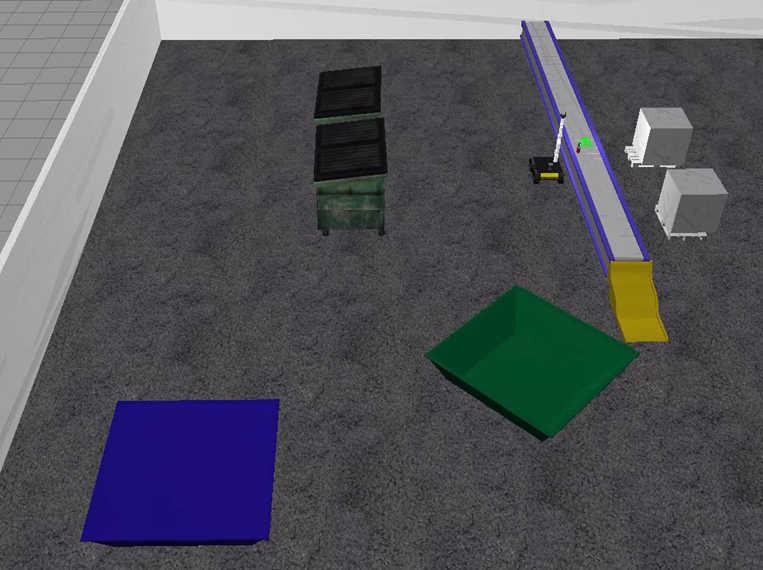

- The simulated mobile manipulator that is a Kinova Gen3 manipulator on a Husky mobile robot

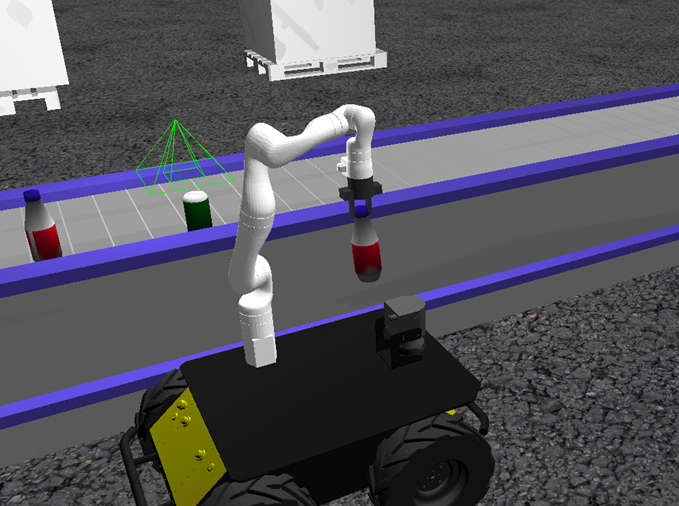

Open the Simulink model to explore the pick-and-place components. 

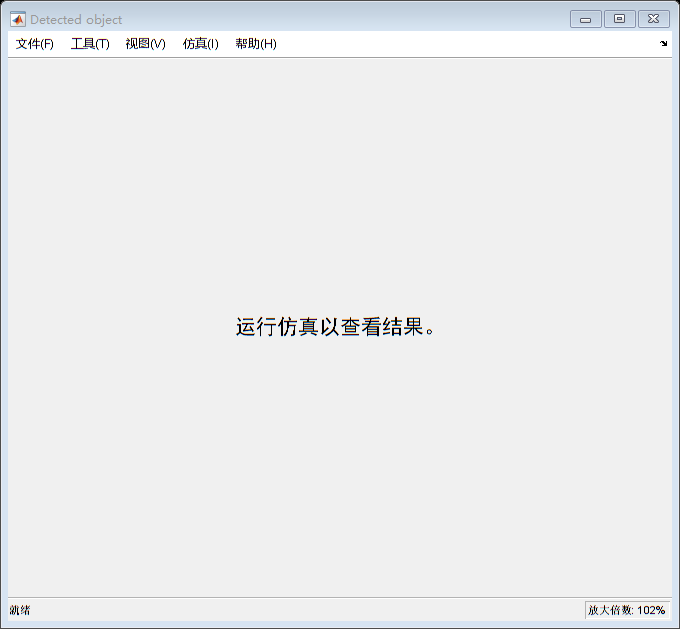

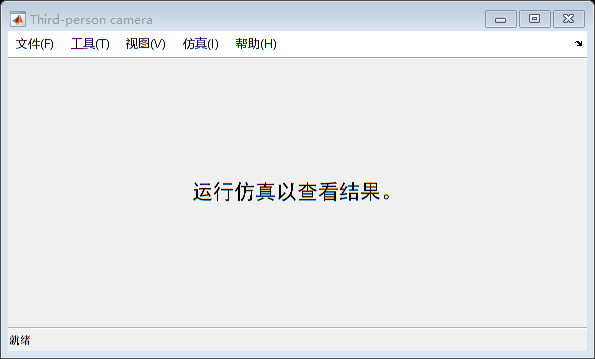

open_system('PickPlaceWorkflowSimulinkMobileArm.slx');

The Simulink model consists of these components:

- `主任务计划程序` — 此 Stateflow 图为移动机械手安排任务以完成拾放作业。 它根据所需的工作流程激活机器人机械手或移动机器人的任务。

- `机械手` — 执行由 `主任务计划程序 `分配给机器人操纵器的任务。 该组件由以下主要模块组成：机械臂调度器、运动规划子系统和感知子系统。

- `移动机器人` — 执行由主调度程序分配给移动机器人的任务。 该组件由以下模块组成：移动机器人调度器、路径规划子系统和路径跟随子系统。

### 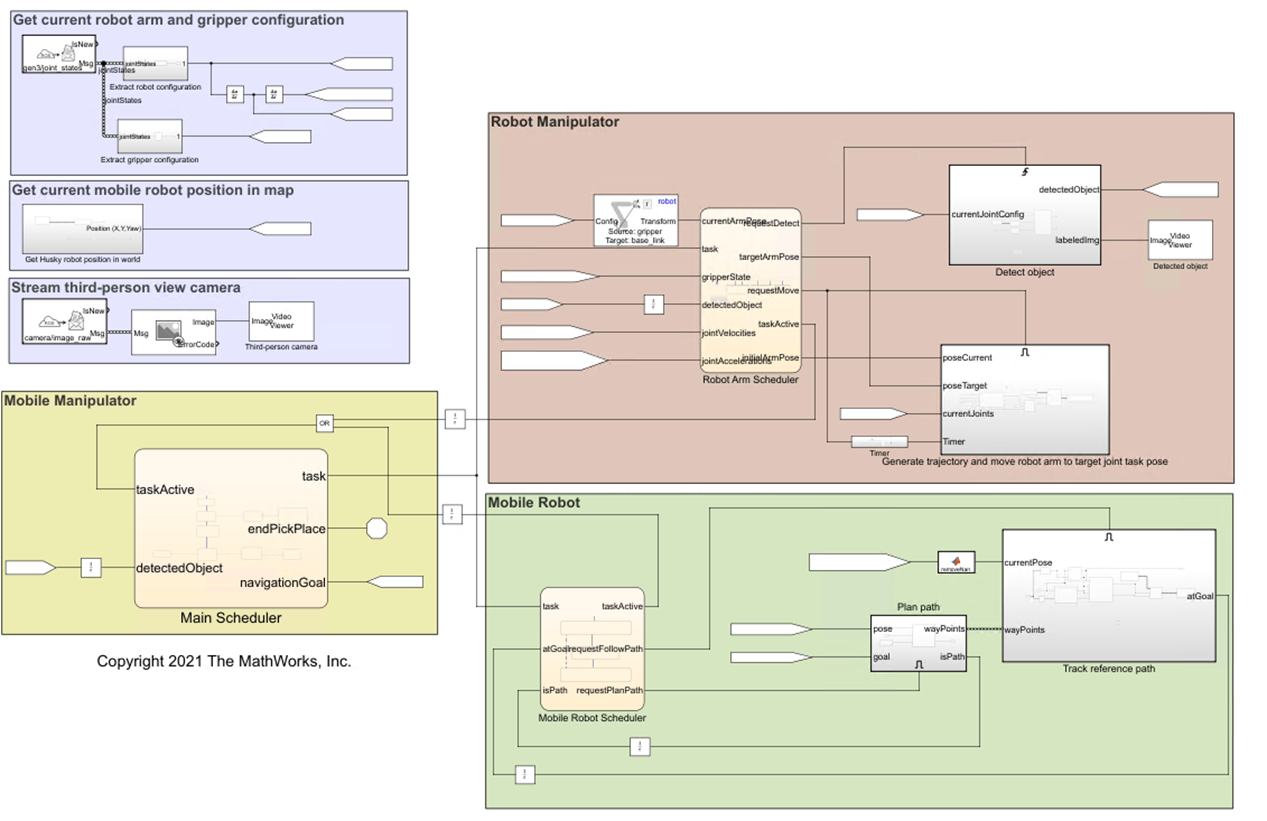

### 1. 主任务计划程序

The model implements the main workflow for the mobile manipulator by using a central Stateflow chart, which follows these steps:

- The mobile manipulator navigates to the conveyer belt to pick up an object to recycle.

- The RGB-D camera on the robot arm detects the poses and types of objects using deep learning.

- The robot arm picks up the detected object.

- The mobile manipulator navigates to the appropriate recycling bin for the detected object type (bottle or can) and places it.

- The robot returns to the conveyer belt and repeats this workflow until no more objects are detected.

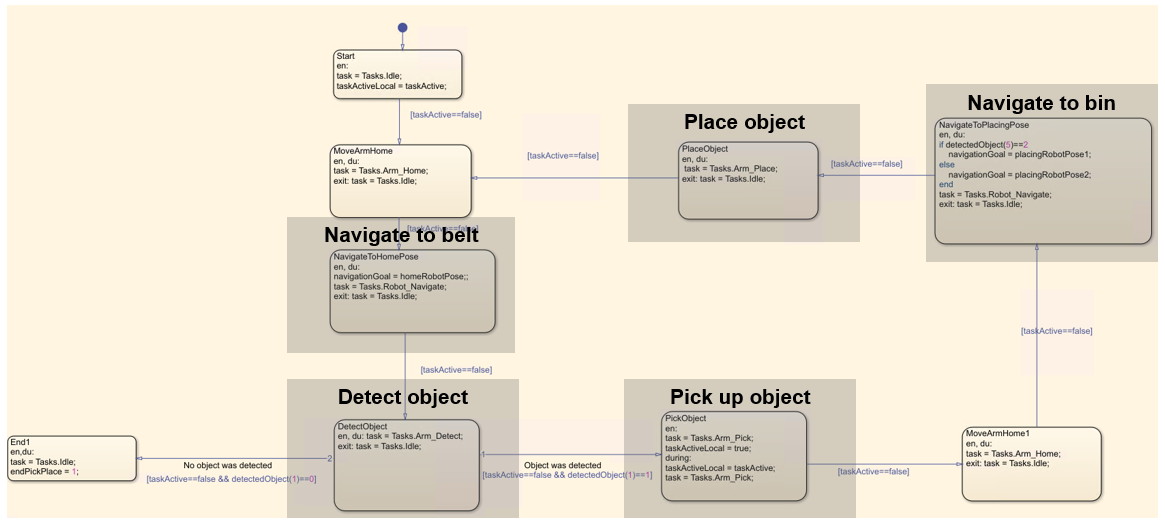

### 2. 机械手

###  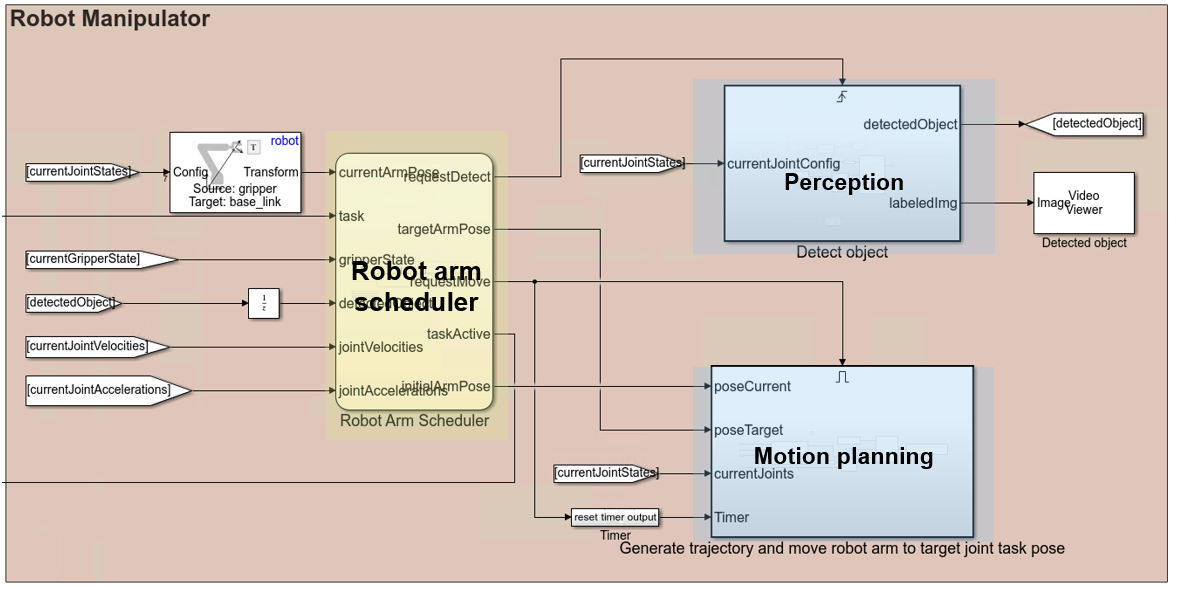

#### A. 机械臂调度器

The robot arm scheduler contains the `Idle`, `MoveToHome`, `Detect`, `PickObject`, and `PlaceObject` states. At any point in time, the robot arm is in one of these states, according to the task ordered by the `Main` `Task` `Scheduler`. To avoid conflict, if the robot arm or mobile robot is in a non-idle state, then the other must be in their idle state. 

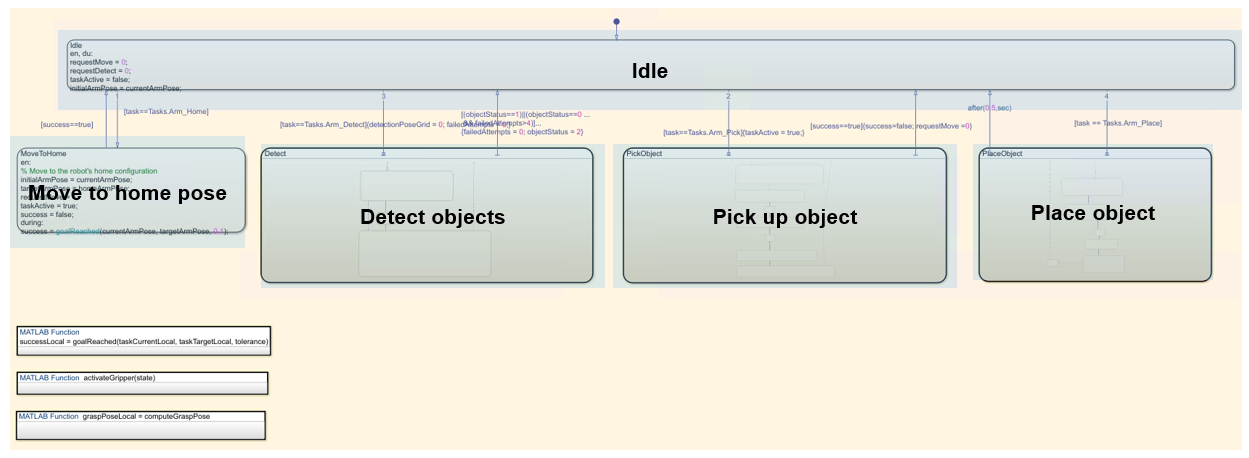

#### B. 运动规划

The motion planning subsystem is an enabled subsystem that, once enabled by a signal from the robot arm scheduler, plans a trajectory and uses the [ros-control](https://wiki.ros.org/ros_control) package to send the command for tracking that trajectory to the joint trajectory controller running in ROS.

The robot arm scheduler sends a signal to *enable* this subsystem when the robot manipulator must move during the pick-and-place workflow. The subsystem remains enabled until the robot reaches the desired target pose. For more information in enabled subsystems, see [Using Enabled Subsystems](docid:simulink_ug#f4-84107).

#### C. 感知

The perception subsystem is a triggered subsystem that applies a pretrained deep learning model to the simulated end-effector camera feed from the robot to detect recyclable parts. The deep learning model takes a camera frame as input and outputs the 2-D location of the object (pixel position) and the type of recycling it requires (blue or green bin). The 2-D location in the image is mapped to the robot base frame using information about the camera properties (focal length  and field of view), the input from the depth sensor, and the robot forward kinematics.

The robot manipulator task scheduler sends a signal to *trigger* this subsystem when the robot must detect the next object during the pick-and-place workflow.For more information on triggered subsystems, see [Using Triggered Subsystems](docid:simulink_ug#f4-84283).

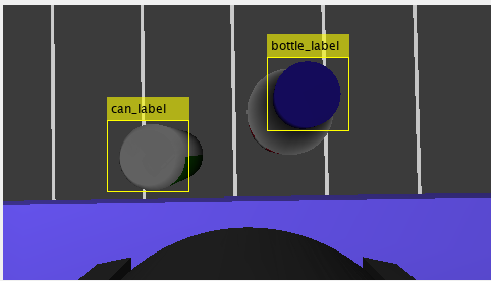

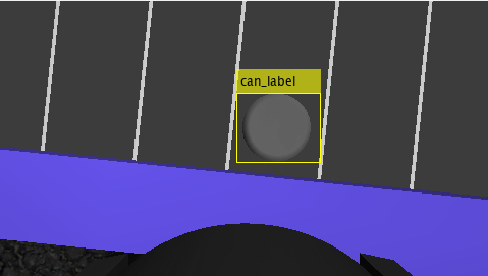

### 3. 移动机器人

The `Mobile` `Robot` workflow consists of a Stateflow chart that governs the overall behavior of the mobile robot, a triggered subsystem that plans the path using a MATLAB function, and a the path following subsystem that uses control logic to follow the reference path.

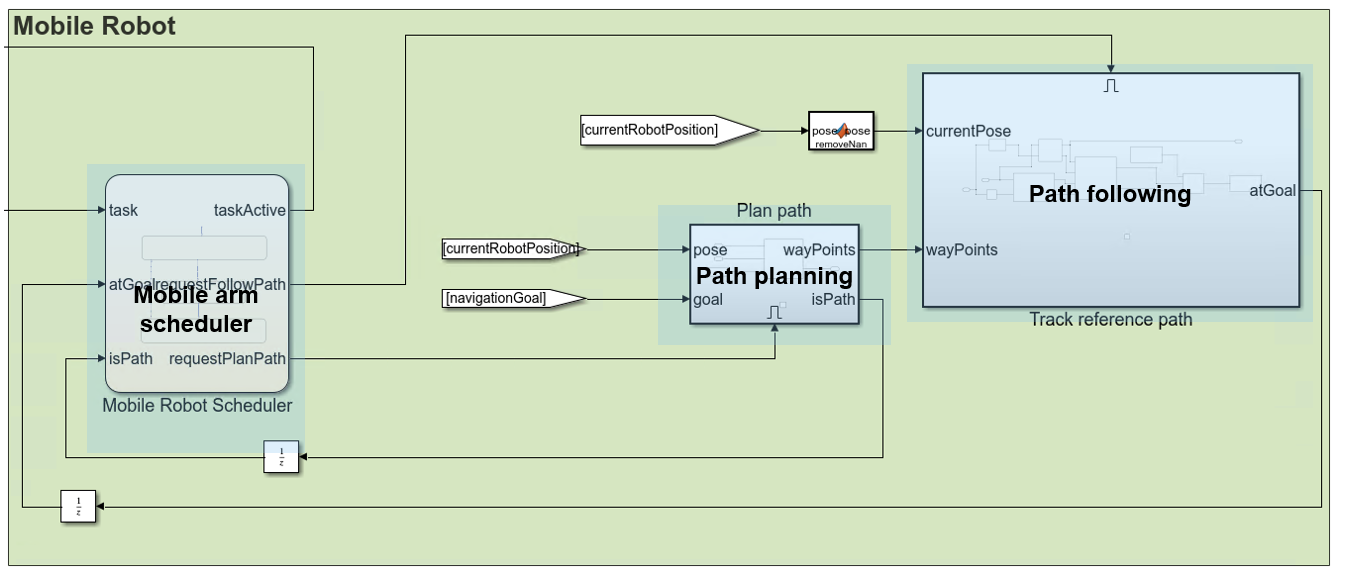

#### 建筑仓库空间图

In order to obtain a map of the workspace, you must first scan the environment. Mount a lidar sensor on the Husky to navigate around the environment and use the `buildmap` function to create an occupancy grid map. For more information, see [Implement Simultaneous Localization And Mapping (SLAM) with Lidar Scans](docid:nav_ug#mw_5bbbbc4c-baae-45e1-b5e0-f2ec90ef5a85).

#### A. 移动机器人调度器

The mobile robot scheduler contains the `Idle`, `PlanPath`, and `FollowPath` states. By default, the mobile robot is in the `Idle` state, meaning that the path planning and path following systems are inactive. The mobile robot scheduler receives task commands from the `Main` `Task` `Scheduler`. Whenthe mobile robot scheduler receives a `Tasks.Robot_Navigate` task, it switches from the `Idle` state to the `PlanPath` state. The scheduler than continues to step, using feedback from the path planning and path following subystems to advance through the stages, ultimately returning to the Idle state, which renders the task inactive and indicates to the `Main` `Task` `Scheduler` that it can move on with high-level tasks. The process then repeats given new inputs from the `Main` `Task` `Scheduler`.

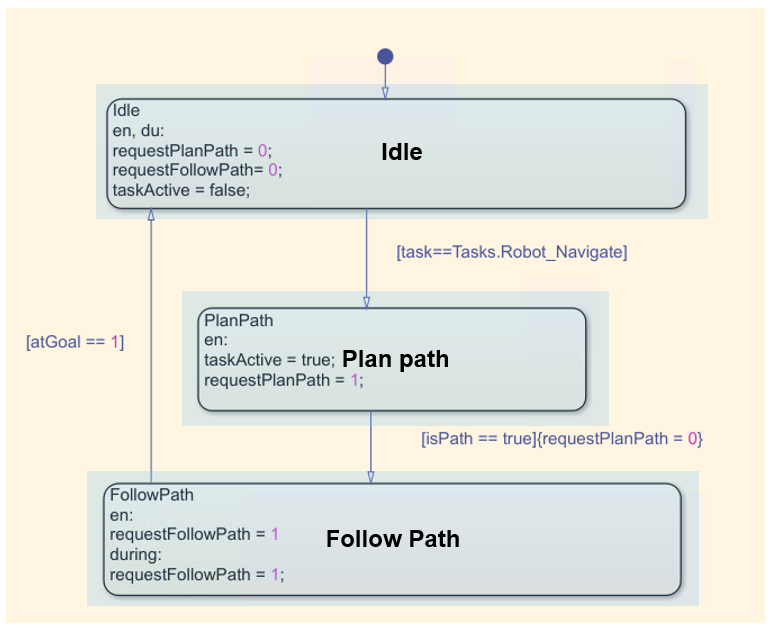

#### B. 路径规划

During the `PlanPath` state, the mobile robot scheduler sets `taskActive` to `true`, which triggers the path planning subsystem. This subsystem contains a MATLAB function block that plans a path on the provided binary occupancy grid map using a `plannerRRTStar` object. The subsystem returns a set of path waypoints in SE(2), as well as a logical flag, `isPath` that indicates whether a path was successfully found. 

Once the mobile robot scheduler receives a value of `true` for `isPath`, it advances to the `FollowPath` state.

#### C. 路径跟随

In the `FollowPath` state, the mobile robot scheduler sets the `requestFollowPath` flag to `true`, which triggers the path following subsystem.

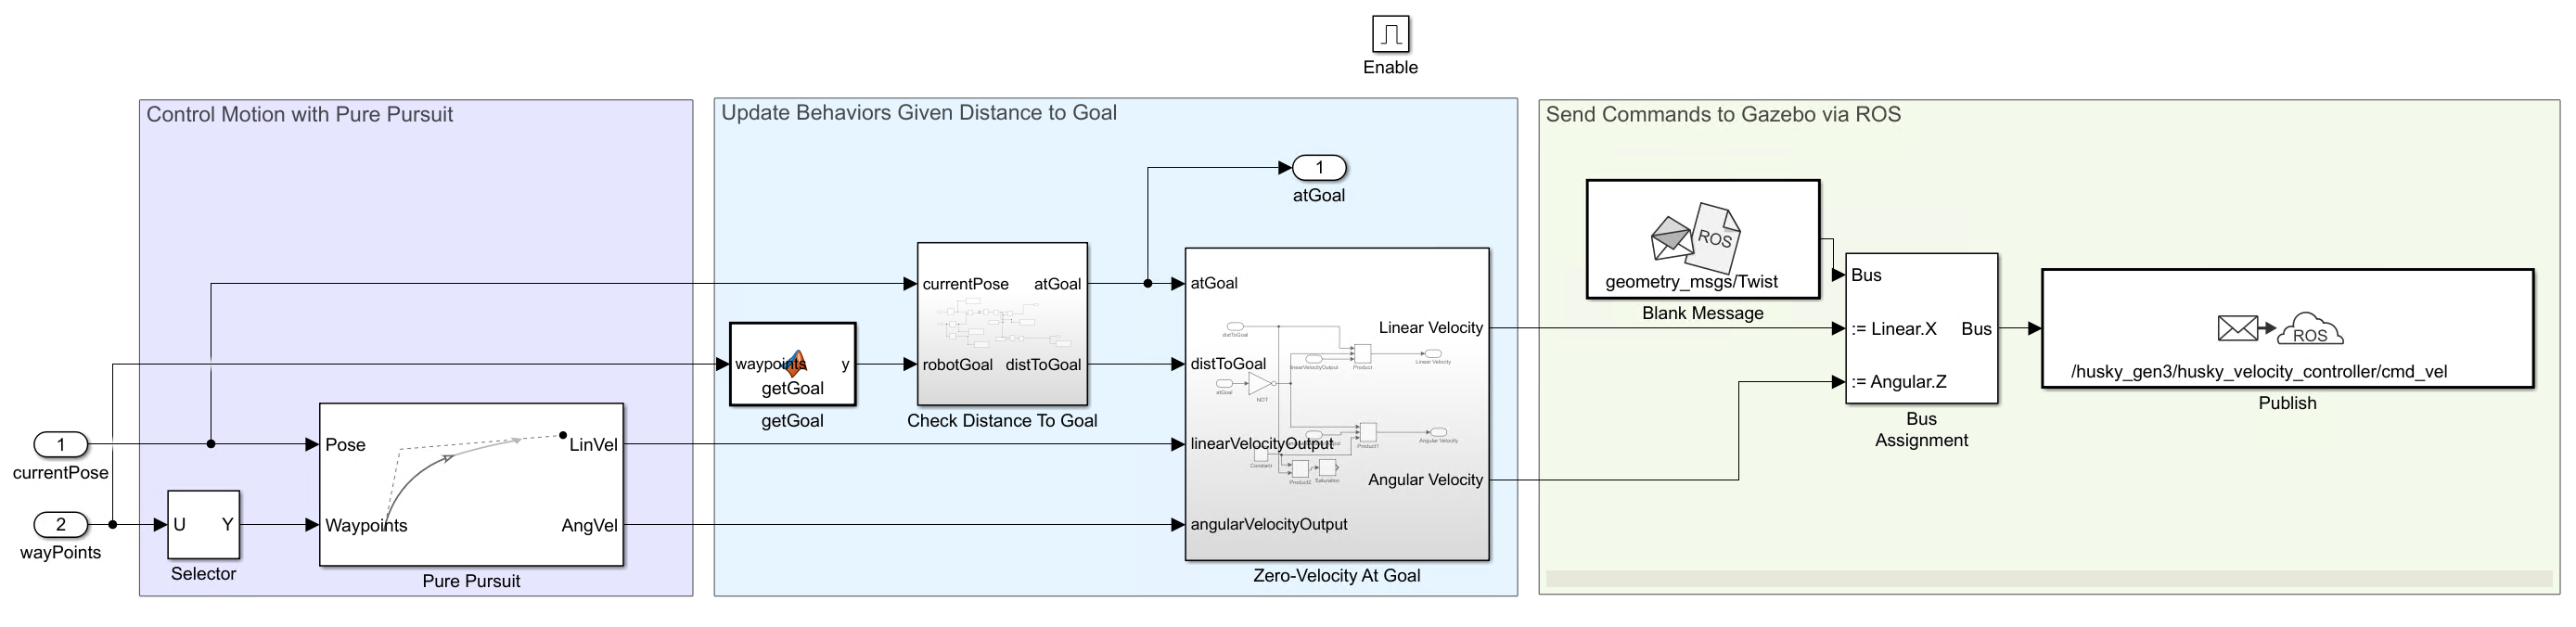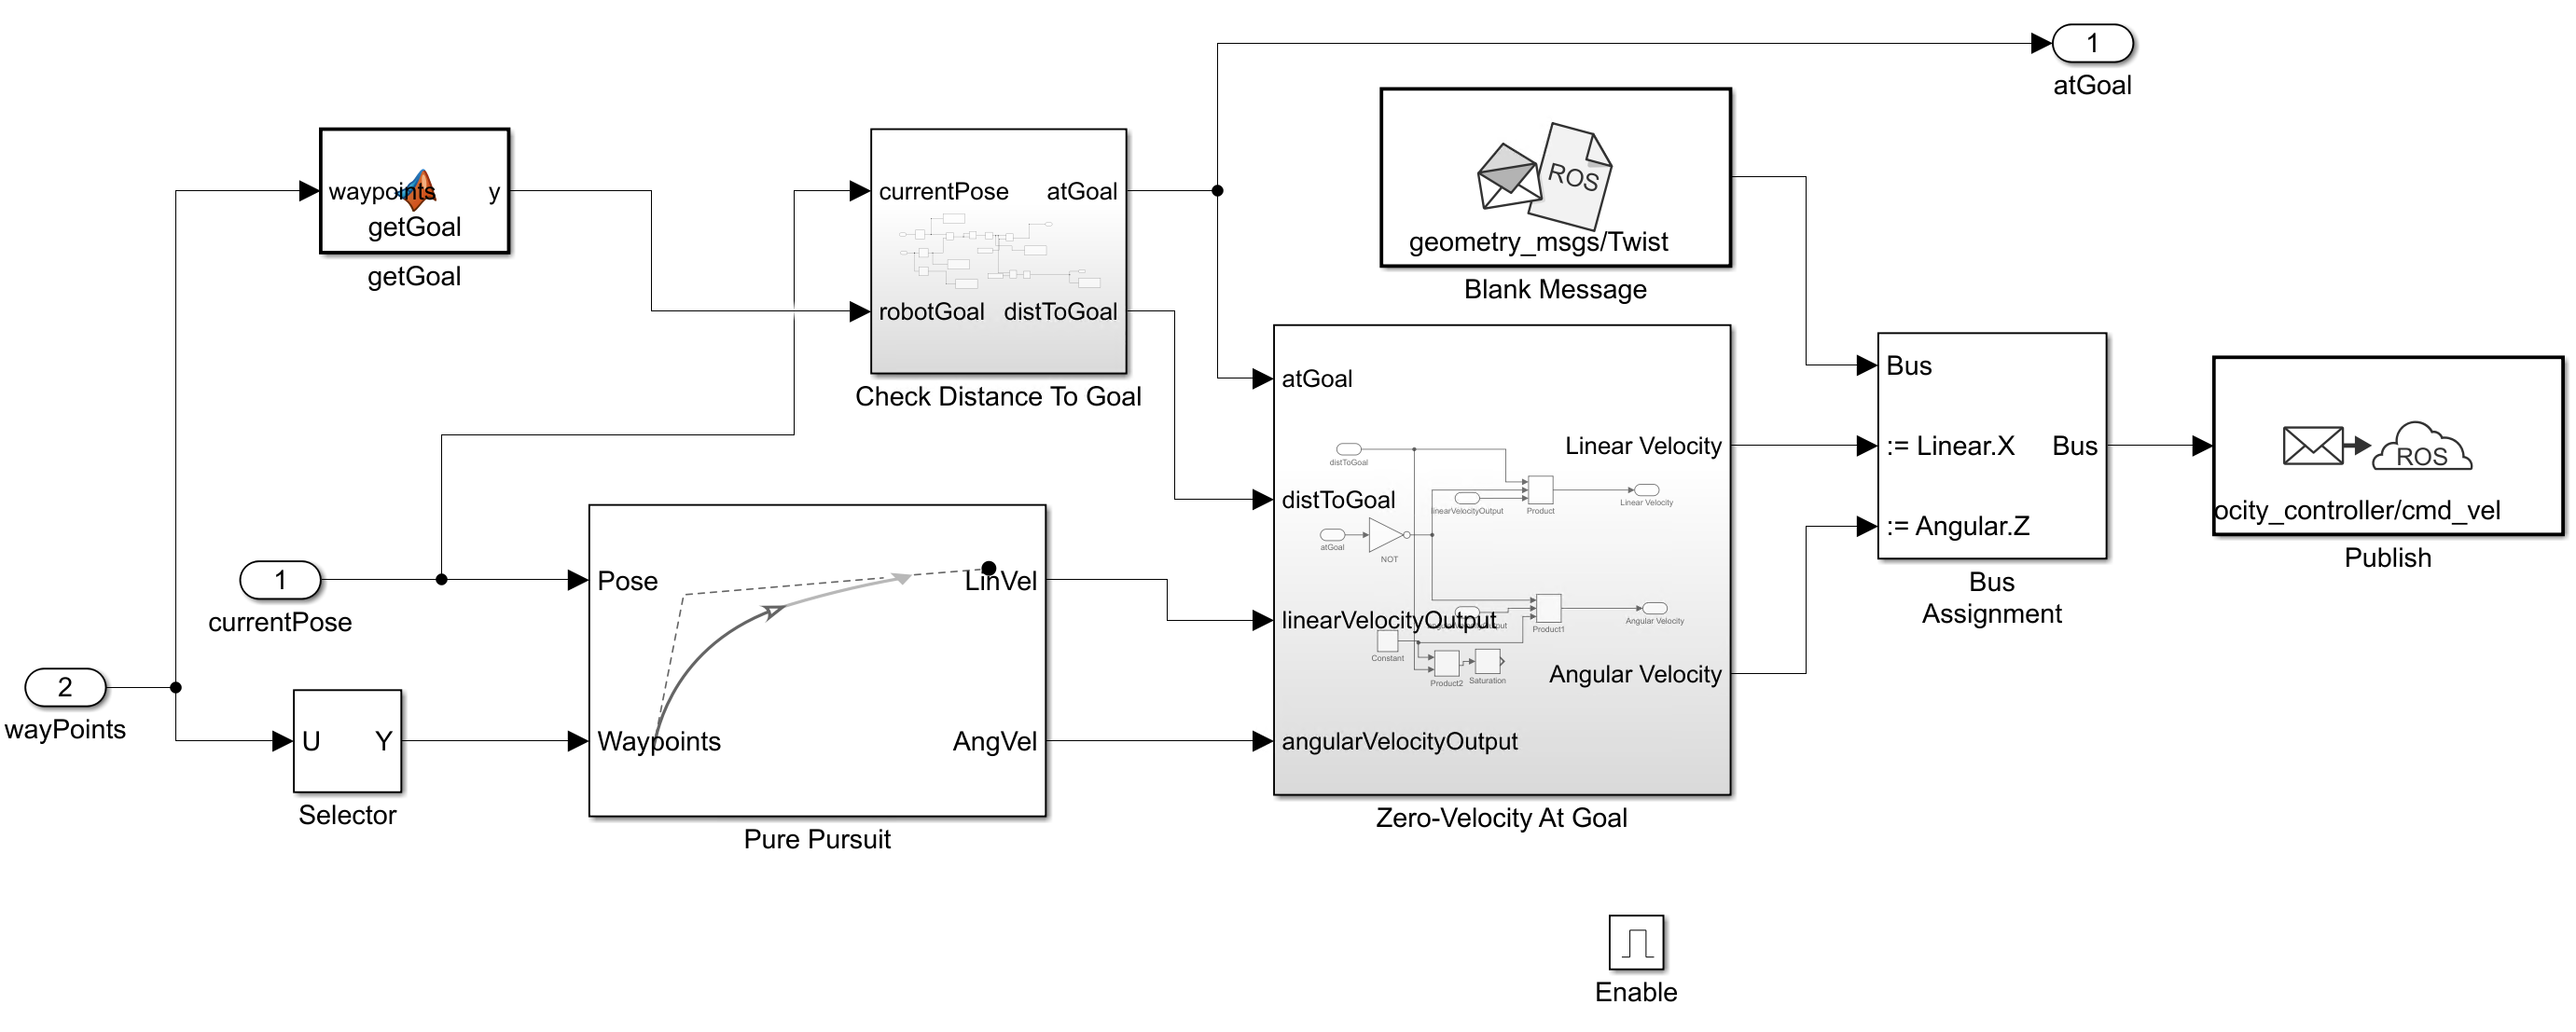

The subsystem has these main parts, listed in the order of execution:

- **Control Motion with Pure Pursuit **— The Pure Pursuit block is the primary motion controller. Given the current pose of the robot and the upcoming waypoint, it assigns a velocity to move the robot to the waypoint. 

- **Update Behaviors Given Distance to Goal **— The `Check` `Distance` `to` `Goal` and `Zero-Velocity` `at` `Goal` subsystems ensure that the robot stops when it has reached the goal. The model also uses the output from the `Check Distance to Goal` subsystem to verify task completion.

- **Send Commands to Gazebo via ROS **— The `Blank` `Message` and `Publish` blocks send the command linear and angular velocities from the `Zero-Velocity` `at` `Goal` subsystem to the appropriate velocity controller on the robot in Gazebo.

Together, these components drive the robot through the Gazebo world. Once the robot reaches the goal, the subsystem returns a value of `true` for `atGoal`, which indicates to the mobile robot scheduler that this state is complete. 

## 分配变量以在模型中使用

要运行 Simulink 模型，必须分配一些与机器人、默认配置和目标姿势相关的参数。

This simulation uses a KINOV8A Gen3 manipulator attached to a Husky mobile robot. For the manipulator, a model of a KINOVA Gen3 with a gripper affixed is stored in a MAT file. Load the robot manipulator rigid body tree.

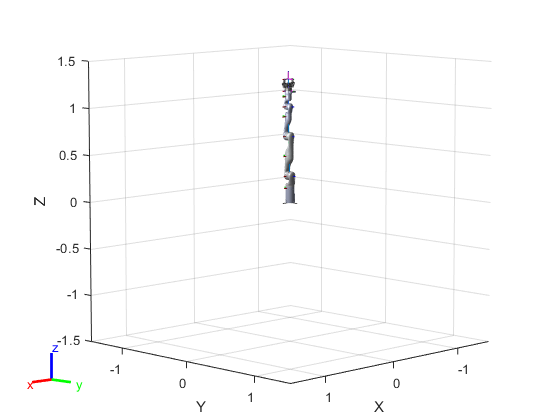

ans =   Axes (Primary) - 属性:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  显示 所有属性

load("helperKINOVAGen3MobileArmPickPlace.mat");
show(robot)

### 初始化拾取和放置应用程序

Set the initial robot arm configuration and name of the end-effector body.

initialRobotJConfig = [1.583 0.086 -0.092 1.528 0.008 1.528 -0.08];
endEffectorFrame = "gripper";

Specify the home robot arm configuration and two poses for dropping objects of two different types. The first pose corresponds to the blue bin, for objects of type 1, and the second pose corresponds to the green bin, for objects of type 2. 

homeArmPose = trvec2tform([0.0 -0.35 0.4])*axang2tform([0 0 1 -pi/2])*axang2tform([0 1 0 pi]);
detectionArmPose = trvec2tform([0.4 0.0 0.56])*axang2tform([0 0 1 -pi/2])*axang2tform([0 1 0 pi]);
placingArmPose = trvec2tform([0.6 0.0 0.57])*axang2tform([0 0 1 -pi/2])*axang2tform([0 1 0 pi/2])*axang2tform([1 0 0 -1.4]);         

Specify the home mobile robot pose and two poses for dropping objects in the blue and green bins, depending on object type. 

homeRobotPose = [7.95, 10.6, 0]; % x, y, theta
placingRobotPose2 =[13.16, 7.94, -0.92];
placingRobotPose1 = [15.15, 3.8, -1.752]; 

Set the step size for the simulation.

Ts = 0.1;

## 启动拾放工作流程

为 KINOVA Gen3 机器人启动基于 ROS 的模拟器，并配置与机器人模拟器的 MATLAB 连接。 

#### 开始 Gazebo 仿真

此研究使用包含 ROS Melodic 的虚拟机 (VM)，可在[此处](https://www.mathworks.com/support/product/robotics/ros2-vm-installation-instructions-v5.html)下载。 此研究不支持 ROS Noetic，因为它依赖于仅在 ROS Melodic 之前受支持的 ROS 包。

- 启动 Ubuntu® 桌面版。

- 在 Ubuntu 桌面, 点击 **Mobile Manipulator World** 图标为该研究启动 Gazebo 世界编辑器, 或者运行这些命令。

#### 启动 ROS Master 和 Gazebo 接口连接

在 Gazebo 中指定 ROS master 的 IP 地址和端口号，以便 MATLAB 可以与机器人模拟器通信。 在本研究中，Gazebo 中的 ROS 主机位于 192.168.203.128:11311，主机地址为 `192.168.31.1`。 可以将这些替换为与实际 ROS 设备设置相对应的值。 使用 `rosinit` 启动 ROS 1 网络。

问题：找不到虚拟网卡。[解决办法](https://blog.csdn.net/m0_52435951/article/details/124016777)。

rosIP = '192.168.223.128'; % IP address of ROS enabled machine  
rosshutdown % shut down existing connection to ROS
rosinit(rosIP,11311);

Initializing global node /matlab_global_node_12733 with NodeURI http://192.168.223.1:3006/ and MasterURI http://192.168.223.128:11311.


使用 `gzinit` 初始化 Gazebo 接口。

gzinit(rosIP);

#### 初始化模型

 使用 ROS 在 Gazebo 中设置初始手臂姿势。

configResp = helperSetCurrentRobotJConfig(initialRobotJConfig);   

Unpause Gazebo physics.

physicsClient = rossvcclient("gazebo/unpause_physics");
physicsResp = call(physicsClient,"Timeout",3);

加载仓库回收设施的预计算地图。

load("helperRecyclingWarehouseMap.mat");

启动工作流程。 通过在 **Simulation** 选项卡上选择 **Run** 来模拟模型。

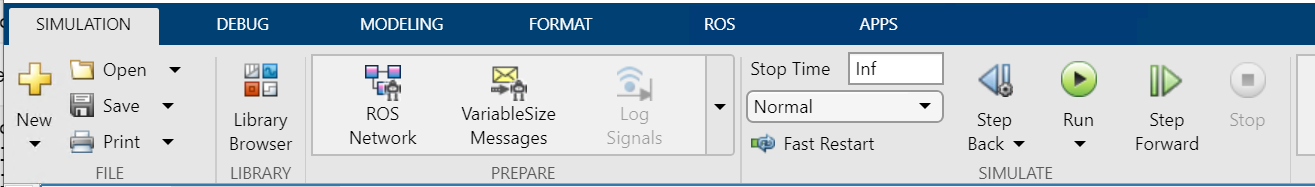

直到模型仿真停止。

一旦两个项目都被移动，模型仍在运行，使用 Gazebo MATLAB 界面重置红瓶和绿罐的位置：

gzlink('set','Green Can','link','Position',[7.80007 11.2462 0.736121],'Orientation',[1 0 0 0]);

STATUS:  Succeed


MESSAGE:  Parameter set successfully.




gzlink('set','Red Bottle','link','Position',[7.932210479374374  11.287119941912177 0.783803767011424],'Orientation',[1 0 0 0]);

STATUS:  Succeed


MESSAGE:  Parameter set successfully.




您还可以更改位置值以在不同位置上试用控制器。 MATLAB 界面使您能够通过使用 [gzlink](https://ww2.mathworks.cn/help/robotics/ref/gzlink.html) （指定或者获取 Gazebo 模型连接信息）和 [gzmodel](https://ww2.mathworks.cn/help/robotics/ref/gzmodel.html) （指定或获取 Gazebo 模型信息）等函数的命令直接从 MATLAB 控制 Gazebo 世界。

重新启动模型：

- 关闭并在 Ubuntu VM 上重新运行脚本。 或者，如果使用终端和命令列表，只需关闭 (Ctrl+C) 并再次调用 roslaunch 命令：

- 从 MATLAB 端的 Initialize Model 部分开始运行设置命令，在 Simulink 中，选择 **Run**。